# Open AI Caribbean Challenge: Mapping Disaster Risk from Aerial Imagery 

## Getting Started with MATLAB

Hello all! We at MathWorks, in collaboration with DrivenData, are excited to bring you this challenge. Through this challenge we plan to provide you the real-world experience of working with a dataset of drone aerial imagery (big images) for classification. We also encourage you to use MATLAB and its various toolboxes to train your model.

This challenge focuses on the disaster risk management of cities which are prone to natural hazards. You are provided with large aerial images captured by drones of regions in Colombia, St. Lucia, and St. Guatemala. The data includes aerial imagery and GeoJSON files including the building footprint, unique building ID, and roof material labels (for the training data).

The dataset is around 30GB in total. Within it there are 3 folders for each country - Colombia, Guatemala, and St. Lucia. Each country's folder consists of subfolders of areas/regions. For instance, within "Colombia" we have 2 regions named **"borde_rural"** and **"borde_soacha"**. Each region's folder has 

- A BigTIFF image file of the region -- for example, `borde_rural_ortho-cog.tif`

- GeoJSON files with metadata on the image extent in latitude/longitude, training data, and test data

Below we are providing a basic Benchmark starter code in MATLAB. In this code we will walk through a basic classification model, where we are training a deep neural network classifier using transfer learning on a pretrained model. Then, we are using this model predict building materials on test data and saving a CSV file in the format required for the challenge. 

This should serve as basic code where you can start analyzing the data and work towards developing a more efficient, optimized, and accurate model using more of the training data available.

On the challenge's [Problem Description](https://www.drivendata.org/competitions/58/disaster-response-roof-type/page/143/) page, all required details for images, features, labels and submission metrics are provided.

So, let's get started with this dataset!

## LOADING AND PREPARING DATA

### Load the data as a bigimage

We are adding the path of the data folder `stac` and an array of strings of the two region names we are training on. As you will be training on all the regions either you can add the names of all the regions on the array or for a more efficient way to work is through reterieving files within the subfolders. 

addpath(genpath("stac")); % Change to whichever folder on your machine contains the dataset
regionNames = ["borde_rural","borde_soacha"];

[`bigimage`](https://www.mathworks.com/help/images/ref/bigimage.html) is a new Image Processing Toolbox function in MATLAB R2019b for processing very large images that may not fit in memory. So here we are creating bigimage objects for the BigTIFF image of each region. 

for idx = 1:numel(regionNames)
    bimg = bigimage(which(regionNames(idx) + "_ortho-cog.tif"));

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


### Split the image into the RGB channel and the mask

Once we have our `bigimage` we notice that the image has 4 channels - 3 channels of RGB and a 4th mask channel of opacity. With the use of the helper function `separateChannels` we are removing the opacity mask channel. For further training we will only be using the 3 RGB channels. 

NOTE: This will take some time to process. You can set the `UseParallel` flag to `true`, which will speed things by starting a parallel pool that uses multiple CPU cores on your machine.

    brgb(idx) = apply(bimg,1, @separateChannels,'UseParallel',true);

### Set the spatial reference for the bigimage

Since each region's image spans a rectangular region with a particular latitude and longitude extent, we want to assign this as the spatial reference for the image. This will allow us to extract image regions by using the latitude and longitude value rather than the pixel values, which we will need to do later.

For more information, refer to the [Set Spatial Referencing for Big Images](https://www.mathworks.com/help/releases/R2019b/images/set-spatial-referencing-for-big-image.html) example in the documentation.

Parse the GeoJSON files providing the bounding box of the entire region

    fid = fopen(regionNames(idx) + "-imagery.json");
    imageryStructs(idx) = jsondecode(fread(fid,inf,'*char')');
    fclose(fid);

Use the bounding boxes parsed out to set the X and Y world limits to the longitude and latitude extents

    for k = 1:numel(brgb(idx).SpatialReferencing)
        brgb(idx).SpatialReferencing(k).XWorldLimits = [imageryStructs(idx).bbox(1) imageryStructs(idx).bbox(3)]; % Longitude limits
        brgb(idx).SpatialReferencing(k).YWorldLimits = [imageryStructs(idx).bbox(2) imageryStructs(idx).bbox(4)]; % Latitude limits
    end
    
end
clear bimg

### Create Training Data

The training set consists of 3 pieces of information that can be parsed from the GeoJSON files for each region

- The building ID

- The building polygon coordinates (in latitude-longitude points)

- The building material

To extract the training set, we are opening the GeoJSON file of each region, reading it, and decoding the files using the [`jsondecode`](https://www.mathworks.com/help/releases/R2019b/matlab/ref/jsondecode.html) function.

for idx = 1:numel(regionNames)    
    fid = fopen("train-" + regionNames(idx) + ".geojson");
    trainingStructs(idx) = jsondecode(fread(fid,inf,'*char')');
    fclose(fid);
end

Once we have all the values in the `trainingStructs` array we will concatenate all the structures together and get a total number of training set elements.

numTrainRegions = arrayfun(@(x)sum(length(x.features)), trainingStructs);
numTrainRegionsCumulative = cumsum(numTrainRegions);
numTrain = sum(numTrainRegions);
trainingStruct = cat(1, trainingStructs.features);

Now let's create placeholder arrays for the ID, material, and coordinates

trainID = cell(numTrain,1);         % Training data ID
trainMaterial = cell(numTrain,1);   % Training data material
trainCoords = cell(numTrain,1);     % Training data coordinates

  Loop through all training data elements

regionIdx = 1;
for k = 1:numTrain

  Extract the ID, material, and coordinates of each ROI

    trainID{k} = trainingStruct(k).id;
    trainMaterial{k} = trainingStruct(k).properties.roof_material;
    coords = trainingStruct(k).geometry.coordinates;
    if iscell(coords)
        coords = coords{1};
    end
    trainCoords{k} = squeeze(coords);    

Increment the index of regions as we loop through the training set to ensure we are referring to the correct region

    if k > numTrainRegionsCumulative(regionIdx)
        regionIdx = regionIdx + 1;
    end

Correct for coordinate convention by flipping the Y image coordinates of the building region coordinates

    trainCoords{k}(:,2) = brgb(regionIdx).SpatialReferencing(1).YWorldLimits(2)-(trainCoords{k}(:,2)-brgb(regionIdx).SpatialReferencing(1).YWorldLimits(1));
end

Convert the text array of materials to a categorical array for later classification.

trainMaterial = categorical(trainMaterial);

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\training_data\concrete_cement\7a1c66f6.png';
                              ' ...\training_data\concrete_cement\7a1c6d7c.png';
                              ' ...\training_data\concrete_cement\7a1c7646.png'
                               ... and 10353 more
                              }
                      Labels: [concrete_cement; concrete_cement; concrete_cement ... and 10353 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


Clear the training data structures since they have now been parsed into individual arrays.

clear trainingStruct trainingStructs

labelInfo = 5×2 table
         Label         Count
    _______________    _____

    concrete_cement     497 
    healthy_metal      5544 
    incomplete          660 
    irregular_metal    3632 
    other                23 


### **OPTIONAL: Visualize the Training Data**

First, let's visualize a specific region and annotate all the training samples as regions of interest (ROIs). Generating the thousands of polygons and displaying them along with a large image is a graphics and computation intensive process, so it will take some time to run this section.

To execute the following steps, change the `display` flag value to `true`. You can also set the 

display = false;

For more information, refer to the [Extract Training Samples from Big Image](https://www.mathworks.com/help/releases/R2019b/images/extract-big-image-training-data-using-bigimagedatastore.html) example in the documentation.

displayRegion = "borde_rural";
displayRegionNum = find(regionNames==displayRegion);

if  display
    % Find the indices of the overall training structure that correspond to the selected region
    if displayRegionNum == 1
        polyIndices = 1:numTrainRegions(displayRegionNum);
    else
        polyIndices = numTrainRegions(displayRegionNum-1) + 1:numTrainRegions(displayRegionNum);
    end
    
    % Extract the ROI polygons
    polyFcn = @(position) images.roi.Polygon('Position',position);
    polys = cellfun(polyFcn,trainCoords(polyIndices));
    
    % Display the image with ROIs and label the plot
    figure
    bigimageshow(brgb(displayRegionNum))
    xlabel('Longitude')
    ylabel('Latitude')
    set(polys,'Visible','on')
    set(polys,'Parent',gca)
    set(polys,'Color','r')

*[Left] Image of one region with training set ROIs  [Right] Zoomed-in image region in the highlighted region on the left image*

              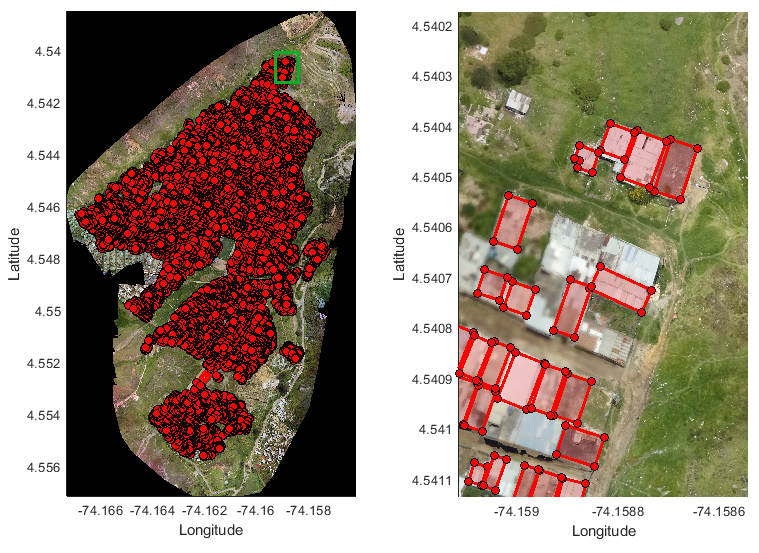                                           

In the following code, we are extracting a few ROIs from the training set at random to verify that the roof regions have been extracted correctly.

    figure
    displayIndices = randi(numTrainRegions(displayRegionNum),4,1);
    for k = 1:numel(displayIndices)
        coords = trainCoords{displayIndices(k) + polyIndices(1) - 1};
        regionImg = getRegion(brgb(displayRegionNum),1, ...
            [min(coords(:,1)) min(coords(:,2))],[max(coords(:,1)) max(coords(:,2))]);
        subplot(2,2,k)
        imshow(regionImg);
    end
end

*Sample ROIs extracted from the training set*

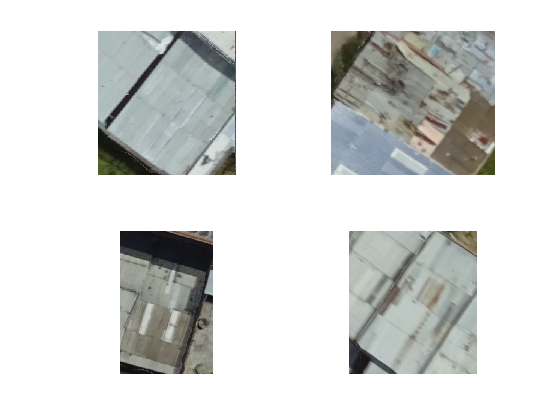

### Save Training Data

Now that we have all the training data, we will extract each building to a separate small image file and place it in a `training_data` folder with subfolders for each material. This will make things easy to set up for training a classification model, as you will see later.

There are also ways to use [`datastore`](https://www.mathworks.com/help/releases/R2019b/matlab/ref/datastore.html) so you don't have to save all the images separately to disk, thus reducing the overhead of generating the training set up front. Instead, you can read chunks from each region's image file only as needed during training. This will likely be slower during training time, but you are welcome to explore this approach if you would like.

If the `training_data` folder already exists, skip this step and simply load the saved training data

if exist("training_data","dir")  
    load(fullfile("training_data","training_data"));

imdsTest =   ImageDatastore with properties:

                       Files: {
                              'C:\Neha_Work\drivendata_caribbeanbenchmark\test_data\7a44da50.png';
                              'C:\Neha_Work\drivendata_caribbeanbenchmark\test_data\7a44db72.png';
                              'C:\Neha_Work\drivendata_caribbeanbenchmark\test_data\7a44dc08.png'
                               ... and 7322 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @(im)readAndResize(im,inputSize)


Else, create a new folder with all the training data, including subfolders for each material label.

NOTE: If you are changing the training set (e.g. changing the number of regions), we recommend deleting any existing `training_data` folder to force the folder to be recreated.       

else

testMaterial = 7325×1 categorical array
     healthy_metal 
     healthy_metal 
     incomplete 
     irregular_metal 
     healthy_metal 
     incomplete 
     incomplete 
     irregular_metal 
     healthy_metal 
     incomplete 
     healthy_metal 
     concrete_cement 
     healthy_metal 
     incomplete 
     irregular_metal 
     healthy_metal 
     irregular_metal 
     healthy_metal 
     concrete_cement 
     irregular_metal 
     healthy_metal 
     healthy_metal 
     healthy_metal 
     healthy_metal 
     healthy_metal 
     irregular_metal 
     healthy_metal 
     healthy_metal 
     irregular_metal 
     healthy_metal 


testScores = 7325×5 single matrix
    0.0044    0.8997    0.0012    0.0930    0.0017
    0.0001    0.9950    0.0000    0.0047    0.0001
    0.0565    0.0167    0.4824    0.4385    0.0058
    0.0007    0.3847    0.0025    0.6119    0.0001
    0.0001    0.8488    0.0017    0.1490    0.0003
    0.0029    0.0953    0.4688    0.4307    0.0024
    0.1648    0.0559    0.3960    0.3809    0.0024
    0.0055    0.0132    0.2002    0.7792    0.0018
    0.0015    0.7648    0.0099    0.2224    0.0015
    0.4453    0.0007    0.5483    0.0051    0.0006


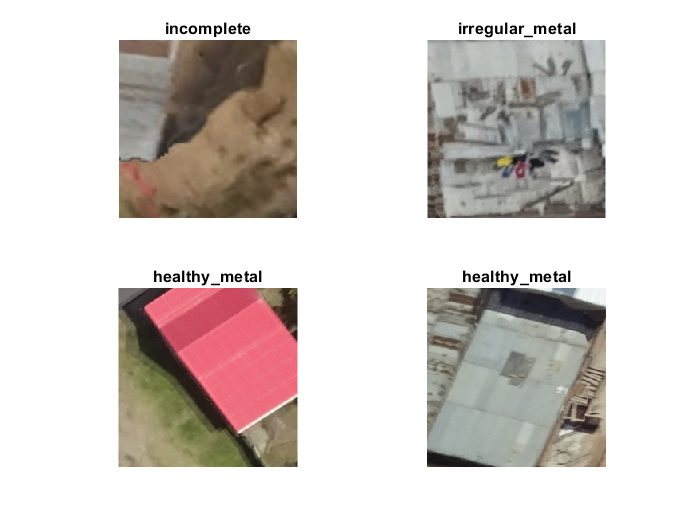

    mkdir("training_data")
    cd training_data
    
    materialCategories = categories(trainMaterial);
    for k = 1:numel(materialCategories)
        mkdir(materialCategories{k})
    end
    cd ..

Extract training images based on the ROIs and save each image to its corresponding material subfolder (NOTE: This will take some time)

    regionIdx = 1;
    for k = 1:numTrain

testResults = 7325×6 table
         id         concrete_cement    healthy_metal    incomplete    irregular_metal      other   
    ____________    _______________    _____________    __________    _______________    __________

    {'7a4d630a'}       0.0044023           0.89972       0.0011677        0.093013        0.0016982
    {'7a4bbbd6'}      0.00013231           0.99503      3.1747e-05       0.0046896       0.00011698
    {'7a4ac744'}        0.056525          0.016738         0.48239         0.43852        0.0058235
    {'7a4881fa'}      0.00071689           0.38473       0.0025458         0.61187       0.00014618
    {'7a4aa4a8'}      0.00013747           0.84884       0.0017315           0.149       0.00028886
    {'7a514434'}       0.0029096          0.095263         0.46878  

Increment the index of regions as we loop through the training set to ensure we are referring to the correct image file when extracting regions.

        if k > numTrainRegionsCumulative(regionIdx)
            regionIdx = regionIdx + 1;
        end

In this step, we are simply getting the lower left and upper right coordinates of the building polygon and cropping out a rectangular region, but you may feel free to try other ways to manipulate the image to extract individual buildings for training.

        coords = trainCoords{k};
        regionImg = getRegion(brgb(regionIdx),1,[min(coords(:,1)) min(coords(:,2))],[max(coords(:,1)) max(coords(:,2))]);
        imgFilename = fullfile("training_data", string(trainMaterial(k)) , trainID{k}+".png" );
        imwrite(regionImg,imgFilename);
    end 

Save the `trainID`, `trainMaterial`, and `trainCoords` variables to a MAT-file to refer to them later without regenerating all the training data.

    save(fullfile("training_data","training_data"),"trainID","trainMaterial","trainCoords")
end

### Create and Save Test Data

Just as we did with the training data, we will now parse the test data GeoJSON files and save the data and images to a `test_data` folder.

The test set consists of 2 pieces of information that can be parsed from the GeoJSON files for each region

- The building ID

- The building polygon coordinates (in latitude-longitude points)

If the folder already exists, skip this step and simply load the saved test data

if exist("test_data","dir")  
    load(fullfile("test_data","test_data"));

Else, create a new folder with all the test data.

NOTE: If you are changing the test set (e.g. changing the number of regions), we recommend deleting any existing `test_data` folder to force the folder to be recreated.       

else
    mkdir("test_data")

First, we will set up `bigimage` variables for all regions with test labels (which are all except Castries and Gros Islet). You won't have to redo this step if these are the same regions you used for training.

    regionNames = ["borde_rural","borde_soacha","mixco_1_and_ebenezer","mixco_3","dennery"];
    for idx = 1:numel(regionNames)
        bimg = bigimage(which(regionNames(idx) + "_ortho-cog.tif"));
        brgb(idx) = apply(bimg,1, @separateChannels,'UseParallel',true);
        fid = fopen(regionNames(idx) + "-imagery.json");
        imageryStructs(idx) = jsondecode(fread(fid,inf,'*char')');
        fclose(fid);
        for k = 1:numel(brgb(idx).SpatialReferencing)
            brgb(idx).SpatialReferencing(k).XWorldLimits = [imageryStructs(idx).bbox(1) imageryStructs(idx).bbox(3)]; % Longitude limits
            brgb(idx).SpatialReferencing(k).YWorldLimits = [imageryStructs(idx).bbox(2) imageryStructs(idx).bbox(4)]; % Latitude limits
        end
    end
    clear bimg

Then, we are opening the GeoJSON file of each region with test labels, reading it, and decoding the files using the [`jsondecode`](https://www.mathworks.com/help/releases/R2019b/matlab/ref/jsondecode.html) function.

    for idx = 1:numel(regionNames)
        fid = fopen("test-" + regionNames(idx) + ".geojson");
        testStructs(idx) = jsondecode(fread(fid,inf,'*char')');
        fclose(fid);
    end

Once we have all the values in the `testStructs` array we will concatenate all the structures together and get a total number of test set elements.

    numTestRegions = arrayfun(@(x)sum(length(x.features)), testStructs);
    numTestRegionsCumulative = cumsum(numTestRegions);
    numTest = sum(numTestRegions);
    testStruct = cat(1, testStructs.features);

Now let's create placeholder arrays for the ID and coordinates

    testID = cell(numTest,1);         % Test data ID
    testCoords = cell(numTest,1);     % Test data coordinates

  Loop through all test data elements

    regionIdx = 1;
    for k = 1:numTest

  Extract the ID and coordinates of each ROI

        testID{k} = testStruct(k).id;
        coords = testStruct(k).geometry.coordinates;
        if iscell(coords)
            coords = coords{1};
        end
        testCoords{k} = squeeze(coords);

Increment the index of regions as we loop through the training set to ensure we are referring to the correct region

        if k > numTestRegionsCumulative(regionIdx)
            regionIdx = regionIdx + 1;
        end

Correct for coordinate convention by flipping the Y image coordinates of the building region coordinates

        testCoords{k}(:,2) = brgb(regionIdx).SpatialReferencing(1).YWorldLimits(2)-(testCoords{k}(:,2)-brgb(regionIdx).SpatialReferencing(1).YWorldLimits(1));
    end

Clear the test data structures since they have now been parsed into individual arrays.

    clear testStruct testStructs

Extract training images based on the ROIs and save each image to its corresponding material subfolder (NOTE: This will take some time)

    regionIdx = 1;
    for k = 1:numTest

Increment the index of regions as we loop through the test set to ensure we are referring to the correct image file when extracting regions.

        if k > numTestRegionsCumulative(regionIdx)
            regionIdx = regionIdx + 1;
        end

In this step, we are simply getting the lower left and upper right coordinates of the building polygon and cropping out a rectangular region, but you may feel free to try other ways to manipulate the image to extract individual buildings for test.

        coords = testCoords{k};
        regionImg = getRegion(brgb(regionIdx),1,[min(coords(:,1)) min(coords(:,2))],[max(coords(:,1)) max(coords(:,2))]);
        imgFilename = fullfile("test_data", testID{k}+".png" );
        imwrite(regionImg,imgFilename);
    end

Save the `testID` and `testCoords` variables to a MAT-file to refer to them later without regenerating all the test data.

    save(fullfile("test_data","test_data"),"testID","testCoords")
end

## EXPLORING THE DATA

### Create Image Datastore from Saved Training Images

First we will create an [`imageDatastore`](https://www.mathworks.com/help/releases/R2019b/matlab/ref/matlab.io.datastore.imagedatastore.html) for the training_data folder. This is used to manage a collection of image files, where each individual image fits in memory, but the entire collection of images does not necessarily fit. 

To further augment and preprocess the data images we recommend looking at the following resources:

- [Preprocess Images for Deep Learning](https://www.mathworks.com/help/releases/R2019b/deeplearning/ug/preprocess-images-for-deep-learning.html)

- [Augment Images for Deep Learning Workflows Using Image Processing Toolbox](https://www.mathworks.com/help/releases/R2019b/deeplearning/examples/image-augmentation-using-image-processing-toolbox.html)

imds = imageDatastore("training_data","IncludeSubfolders",true, ...
    "FileExtensions",".png","LabelSource","foldernames")

Show a count of the distribution of all 5 materials. Notice that the number of samples for each material can be quite different, which means the classes are not balanced. This could affect the performance of your model if you do not address this, since this may bias the model to predict materials that are more frequent in the training set.

labelInfo = countEachLabel(imds)

## TRAINING A NEURAL NETWORK USING TRANSFER LEARNING

### Configure Pretrained Network for Transfer Learning

In this example we use the [ResNet-18 neural network](https://www.mathworks.com/help/releases/R2019b/deeplearning/ref/resnet18.html) as a baseline for our classifier. You can also use other networks to perform [transfer learning](https://www.mathworks.com/help/releases/R2019b/deeplearning/examples/train-deep-learning-network-to-classify-new-images.html). 

*NOTE: You will first have to download the Deep Learning Toolbox Model for ResNet-18 Network support package.*

net = resnet18;

To retrain ResNet-18 to classify new images, replace the last fully connected layer and the final classification layer of the network. In ResNet-18, these layers have the names `'fc1000'` and `'ClassificationLayer_predictions'`, respectively. Set the new fully connected layer to have the same size as the number of classes in the new data set. To learn faster in the new layers than in the transferred layers, increase the learning rate factors of the fully connected layer using the `'WeightLearnRateFactor'` and `'BiasLearnRateFactor'` properties.

numClasses = numel(categories(imds.Labels));
lgraph = layerGraph(net);

newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newFCLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

View the modified network using the [`analyzeNetwork`](https://www.mathworks.com/help/releases/R2019b/deeplearning/ref/analyzenetwork.html) function. You can also open it using the [Deep Network Designer app](https://www.mathworks.com/help/releases/R2019b/deeplearning/ref/deepnetworkdesigner-app.html).

analyzeNetwork(lgraph);

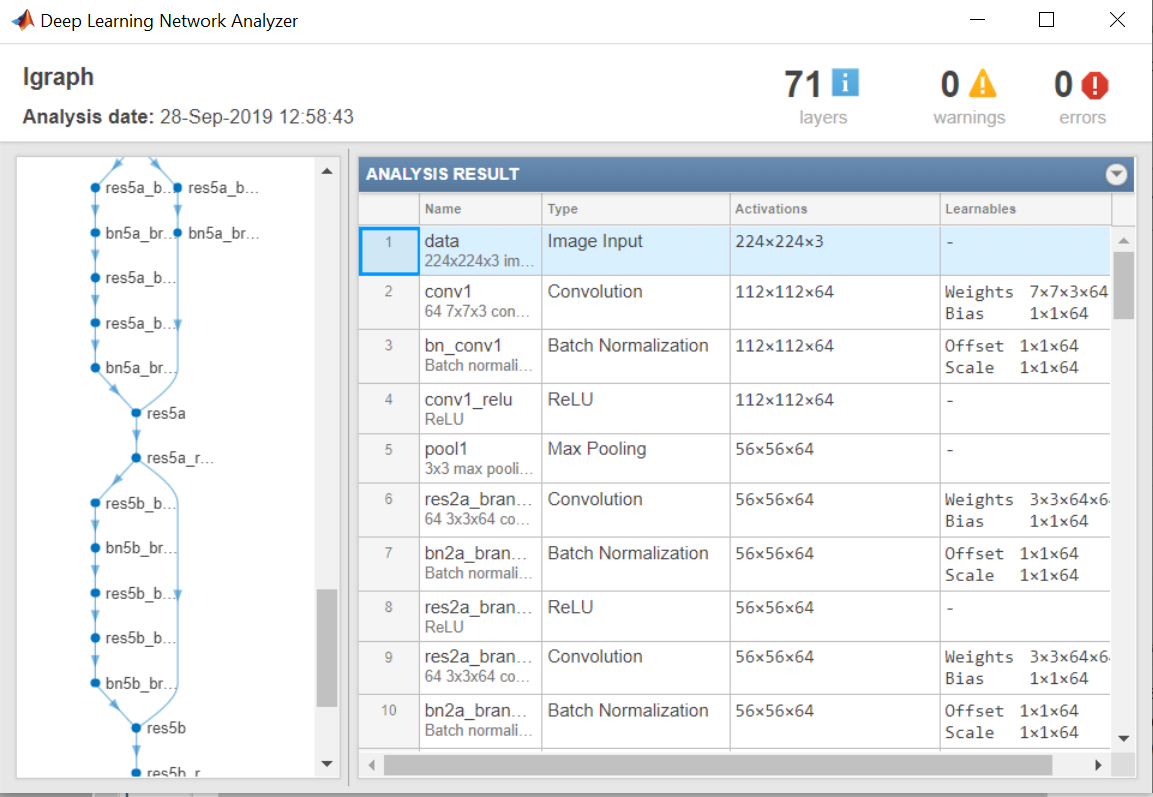

### Set up training options

Configure the image datastore to use the neural network's required input image size. To do this, we are registering a custom function called `readAndResize` (which you can find at the end of this script) and setting it as the `ReadFcn` in the datastore.

inputSize = net.Layers(1).InputSize;
imds.ReadFcn = @(im)readAndResize(im,inputSize); % Refers to a helper function at the end of this script

Split the training data into training and validation sets. Note that this is randomly selecting a split, but you may want to look into the [`splitEachLabel`](https://www.mathworks.com/help/releases/R2019b/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) function for other options to make sure the classes are balanced

[imdsTrain,imdsVal] = splitEachLabel(imds,0.7,"randomized");

Specify the training options, including mini-batch size and validation data. Set `InitialLearnRate` to a small value to slow down learning in the transferred layers. In the previous step, you increased the learning rate factors for the fully connected layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning only in the new layers and slower learning in the other layers.

You can work with different options to improve the training. Check out the [documentation for trainingOptions](https://www.mathworks.com/help/releases/R2019b/deeplearning/ref/trainingoptions.html) to learn more.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsVal, ...
    'ValidationFrequency',floor(numel(imdsTrain.Files)/(32*2)), ...
    'Verbose',false, ...
    'Plots','training-progress');

### Train the network

Here you will use the image datastores, neural network layer graph, and training options to train your model.

Note that training will take a long time using a CPU. However, MATLAB will automatically detect if you have a [supported GPU](https://www.mathworks.com/help/releases/R2019b/parallel-computing/gpu-support-by-release.html) to help you accelerate training.

Set the `doTraining` flag below to `false` to load a presaved network.

doTraining = false;
if doTraining
    netTransfer = trainNetwork(imdsTrain,lgraph,options);
else
    load resnet_presaved.mat
end


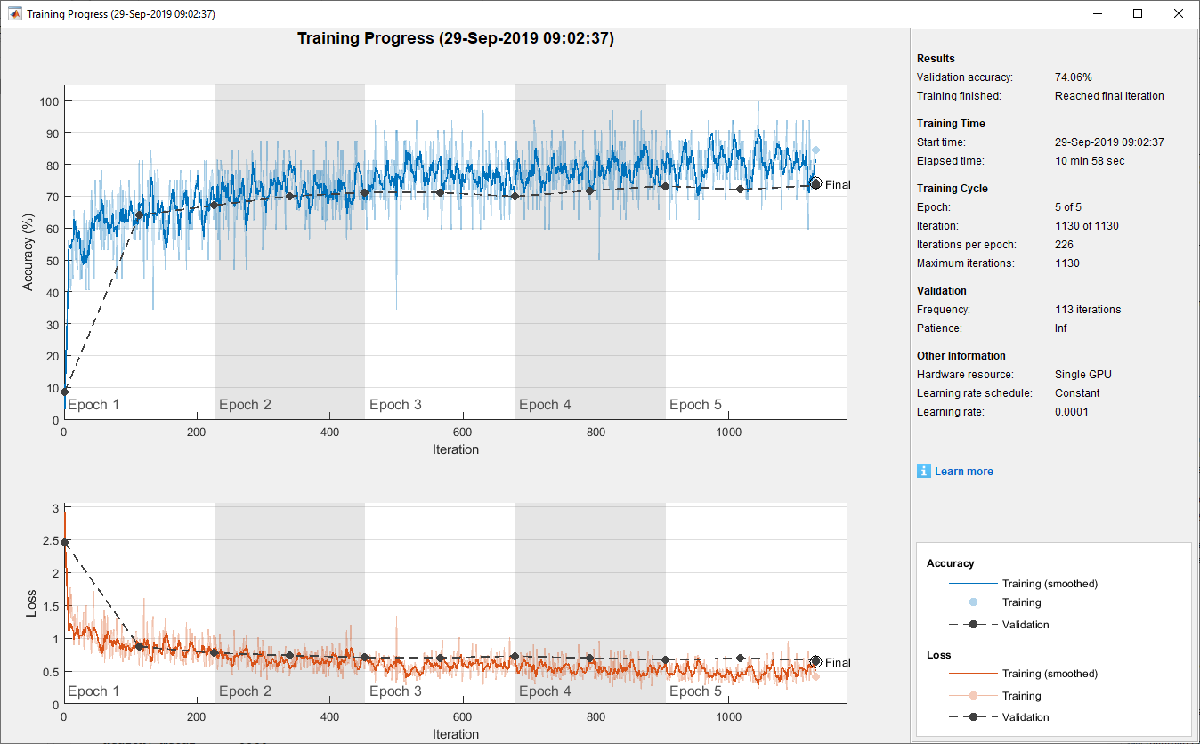

## PREDICTING & SUBMITTING

### Predict on the Test Set

Once we have our trained network, we can perform predictions on our test set. To do so, first we will create an image datastore for the test set.

imdsTest = imageDatastore("test_data","FileExtensions",".png");
imdsTest.ReadFcn = @(im)readAndResize(im,inputSize)

Next we predict labels (`testMaterial)` and scores (`testScores`) using the trained network 

NOTE: This will take some time, but just as with training the network, MATLAB will determine whether you have a supported GPU and significantly speed up this process.

[testMaterial,testScores] = classify(netTransfer,imdsTest)

The following code will display the predicted materials for a few test images. You need to change the `display` flag to `true` to execute the below code. 

figure
displayIndices = randi(numTest,4,1);
for k = 1:numel(displayIndices)
    testImg = readimage(imdsTest,displayIndices(k));
    subplot(2,2,k)
    imshow(testImg);
    title(string(testMaterial(displayIndices(k))),"Interpreter","none")
end

### Save Submission to File

Create a table of the results based on the IDs and prediction scores. The desired file format for submission is:

`id, concrete_cement, healthy_metal, incomplete, irregular_metal, other`

We will place all the test results in a MATLAB table, which makes it easy to visualize and to write to the desired file format.

testResults = table(testID,testScores(:,1),testScores(:,2), ...
    testScores(:,3),testScores(:,4),testScores(:,5), ...
    'VariableNames',['id';categories(testMaterial)])

Write the results to a CSV file. This is the file you will submit for the challenge.

writetable(testResults,'testResults.csv');

Thanks for following along with this code! We are excited to find out how you will modify this starter code and make it yours. We strongly recommend looking at our [Deep Learning Tips & Tricks page](https://www.mathworks.com/help/releases/R2019b/deeplearning/ug/deep-learning-tips-and-tricks.html) for more ideas on how you can improve our benchmark model.

Feel free to reach out to us in the DrivenData forum or email us at studentcompetitions@mathworks.com if you have any further questions.

# Helper Functions

Separates a bigimage into its RGB (1st to 3rd) and mask (4th) channels.

function [rgb, m] = separateChannels(rgbm)
rgb = rgbm(:,:,1:3);
m = logical(rgbm(:,:,4));
end

Read and resize an image to a desired input size

function im = readAndResize(filename,sz)
im = imresize( imread(filename), sz(1:2) );
end

*Copyright 2019 The MathWorks, Inc.*